# Frequency analysis of a one-dimensional data set (a-b)

% Assignment 2. Part (a) - (b)
% Names: Timur Holikov, Lea Ebenschweiger

Warning: The execution time of these two subtasks can exceed 15 minutes (at least this is the case on my computer)

### (a) Write a code that implements the discrete Fourier transform,

#### 
$$Y_k =\sum_{j=0}^{n-1} y_j \;\exp \left(i\;\frac{2\pi \textrm{kj}}{n}\right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;k=0,\ldotp \ldotp \ldotp ,n-1\ldotp$$


[y, SR] = audioread('single_tone.ogg');
y_L = y(:,1); %import left channel
n = length(y_L);

% Find the next power of 2
n_ext = 2^nextpow2(n);

% Extend the signal with zeros
y_ext = [y_L; zeros(n_ext-n, 1)];

Discrete Fourier transfrom:

%% DFT
% tic; Measure the execution time
Y_DFT = zeros(n_ext, 1);
Y_DFT = DFT(n_ext, Y_DFT, y_ext);

Built-in FFT:

%% FFT
Y_FFT = fft(y_ext);

% A negative exponent sign is used in Matlab to define FFT, so one need to
% take the complex conjugate for comparison
Y_FFT = conj(Y_FFT);

#### Comparison of calculation results for the built-in FFT implementation library and “manual” DFT implementation:

disp(norm(Y_FFT - Y_DFT));

   2.7065e-09



The norm of the difference may not be exactly zero due to the round-of errors associated with the numerical representation of complex numbers in MATLAB (finite precision). But if this difference is very close to zero, then one can say that the results are (effectively) equal to each other.

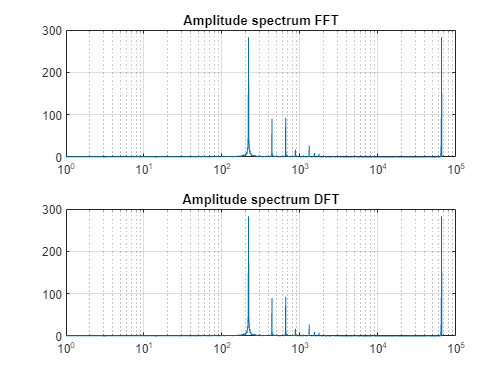

%Plots (just in case)
A1 = abs(Y_FFT);
A2 = abs(Y_DFT);

figure
subplot(2,1,1)
semilogx(A1)
title('Amplitude spectrum FFT')

grid on

subplot(2,1,2)
semilogx(A2)
title('Amplitude spectrum DFT')

grid on

% t = toc; approx. 18 Minutes

### (b) Select a segment of the time series of length m, and modify your code to determine the time it takes to compute the discrete Fourier transform of the segment. Make a plot of the computation time as a function of m and interpret your results.

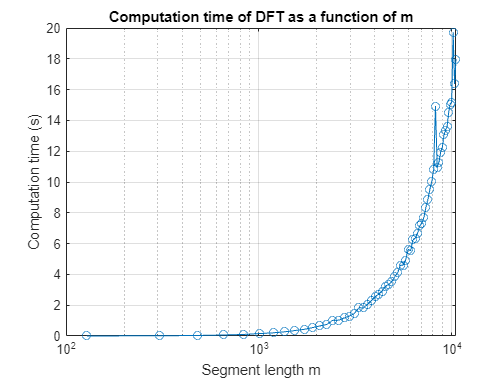

m_values = linspace(128, n/5, 60); % segment lengths
time_values = zeros(size(m_values)); % computation times

for i = 1:length(m_values)
    % m = 2^nextpow2(m_values(i));
    m = round(m_values(i));
    y_segment = y_ext(1:m); % select a segment

    tic; % start timer
    Y_DFT_segment = zeros(m, 1);
    Y_DFT_segment = DFT(m, Y_DFT_segment, y_segment);

    time_values(i) = toc; % stop timer and record time
end

figure
semilogx(m_values, time_values, 'o-')
grid on
xlabel('Segment length m')
ylabel('Computation time (s)')
title('Computation time of DFT as a function of m')

### Local functions:

function Y_DFT = DFT(n, Y_DFT, y)
    for k = 0:n-1
        for j = 0:n-1
            Y_DFT(k+1) = Y_DFT(k+1) + y(j+1)*exp(1i*2*pi*k*j/n);
        end
    end
end